## Continuous Timet    

PitchRateModel = tf(.4323,  [1, 1.334]);
Ri = pid(.3, .3, .05, .01);
Mixer = 66.6667;

Li = Ri * Mixer * PitchRateModel; 
Ti = Li / (1 + Li);
Ti.Name = 'Ti - Continuous Time';

## Discrete Time

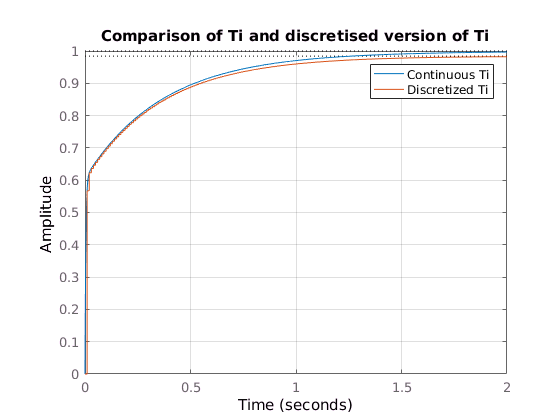

tol = .0025; % Tolerance used for pole/zero cancellation in |minreal|
 
Ti = minreal(Ti, tol);

Ti_dt_block = minreal(c2d(Ti, .01), tol); 
Ti_dt_block.Name = 'Ti_dt_block - Discrete Time';

Li_dt_block = c2d(Li, .01); 
Ti_dt_partial_block = minreal(Li_dt_block / (1 + Li_dt_block), tol); 
Ti_dt_partial_block.Name = 'Ti_dt_partial_block - Discrete Time';

Li_dt_single = c2d(Ri, .01) * Mixer * c2d(PitchRateModel, .01);
Ti_dt_single = minreal(Li_dt_single / (1 + Li_dt_single), tol);
Ti_dt_single.Name = 'Ti_dt_single - Discrete Time';

step(Ti, Ti_dt_block); grid on; 
legend('Continuous Ti', 'Discretized Ti'); 
title('Comparison of Ti and discretised version of Ti')

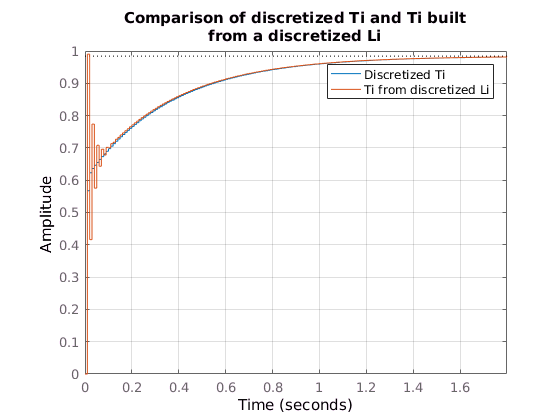


step(Ti_dt_block, Ti_dt_partial_block); grid on;        
legend('Discretized Ti', 'Ti from discretized Li');
title({'Comparison of discretized Ti and Ti built'
    'from a discretized Li'});

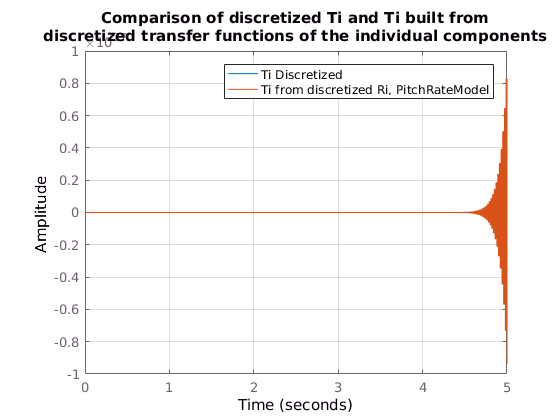


step(Ti_dt_block, Ti_dt_single); grid on;
legend('Ti Discretized', 'Ti from discretized Ri, PitchRateModel');
title({'Comparison of discretized Ti and Ti built from'
    'discretized transfer functions of the individual components'});


zpk(Ti)


ans =
 
   152.75 (s+4.443) (s+1.274)
  -----------------------------
  (s+250.1) (s+2.758) (s+1.254)
 
Name: Ti - Continuous Time
Continuous-time zero/pole/gain model.



zpk(Ti_dt_block)


ans =
 
    0.56724 (z-0.9567)
  ----------------------
  (z-0.9728) (z-0.08203)
 
Name: Ti_dt_block - Discrete Time
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



zpk(Ti_dt_partial_block)


ans =
 
   0.99016 (z-0.9567)
  ---------------------
  (z-0.9727) (z+0.5958)
 
Name: Ti_dt_partial_block - Discrete Time
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



zpk(Ti_dt_single)


ans =
 
   1.5173
  ---------
  (z+1.133)
 
Name: Ti_dt_single - Discrete Time
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.




fprintf('\n');

fprintf('Ti dcgain:                  %f\n', dcgain(Ti));

Ti dcgain:                  1.000000


fprintf('Ti_dt_block dcgain:         %f\n', dcgain(Ti_dt_block));

Ti_dt_block dcgain:         0.984077


fprintf('Ti_dt_partial_block dcgain: %f\n', dcgain(Ti_dt_partial_block));

Ti_dt_partial_block dcgain: 0.984175


fprintf('Ti_dt_single dcgain:        %f\n', dcgain(Ti_dt_single));

Ti_dt_single dcgain:        0.711345


It looks like `Ti_dt_block `has a pole in `0.082 `that moves to `0.5958 `if instead of discretizing `Ti `we discretize `Li. ` This pole seems to move again if we instead of discretizing `Li` we discretize the individual components `Ri `and `PitchRateModel`. Why ?